clear; clc;

The Mean Squared Error is: 16394.074240


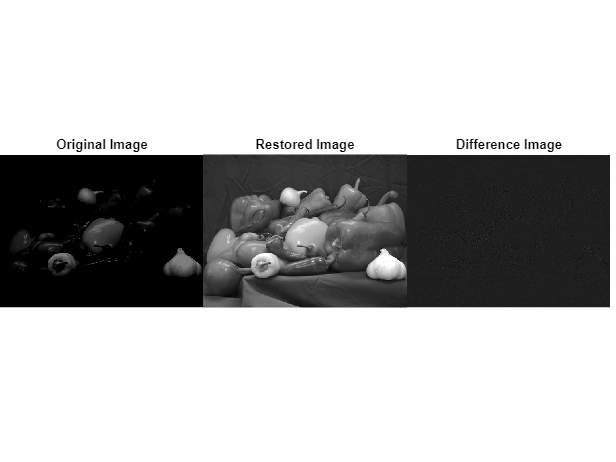

jpeg_baseline_coding('peppers.png', 1);

The Mean Squared Error is: 16388.609485


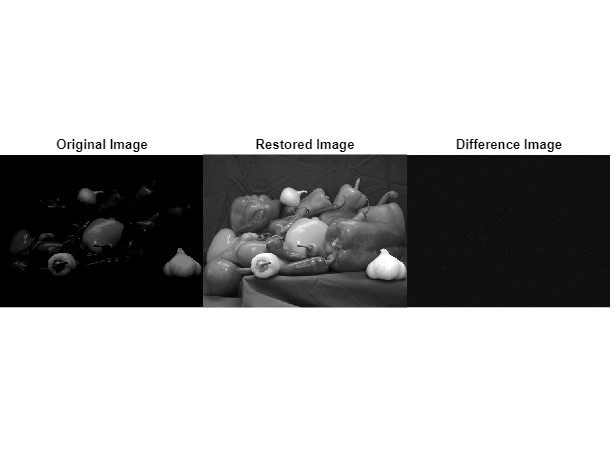


% h) Repeat Parts (a) to (g) for quality factors m = 0.25 and m = 4.00. Comment on the results.
jpeg_baseline_coding('peppers.png', 0.25);

The Mean Squared Error is: 16415.844097


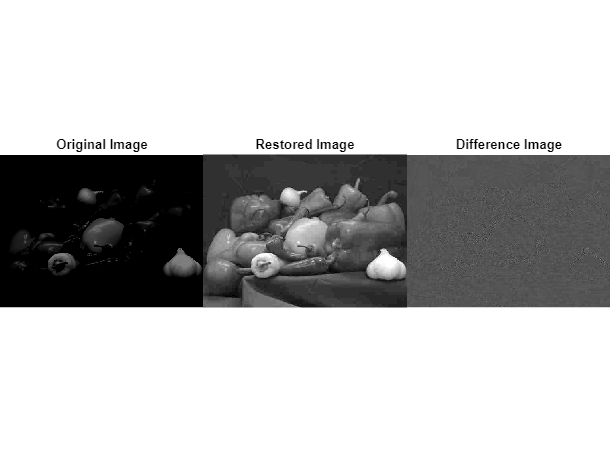

jpeg_baseline_coding('peppers.png', 4);

## Function: JPEG baseline coding

function jpeg_baseline_coding(imagePath, m)
    % a) Read the input image and convert it to gray-scale.
    img = imread(imagePath);
    gray_img = im2gray(img);

    % b) Subtract value 128 from the gray-scale image.
    gray_img = double(gray_img) - 128;

    % Define the quantization matrix
    quant =[ 16, 11, 10, 16, 24, 40, 51, 61;
             12, 12, 14, 19, 26, 58, 60, 55;
             14, 13, 16, 24, 40, 57, 69, 56;
             14, 17, 22, 29, 51, 87, 80, 62;
             18, 22, 37, 56, 68,109,103, 77; 
             24, 35, 55, 64, 81,104,113, 92;
             49, 64, 78, 87,103,121,120,101;
             72, 92, 95, 98,112,100,103, 99];

    % c) Divide the image into non-overlapping blocks of size N*N pixels, where N = 8. 
    % Using function dct2, compute the DCT coefficients of each sub-image.
    fun = @(block_struct) dct2(block_struct.data);
    dct_img = blockproc(gray_img, [8 8], fun);

    % d) Divide the DCT coefficients of each sub-image by the following matrix.
    fun = @(block_struct) round(block_struct.data ./ (quant * m));
    quant_img = blockproc(dct_img, [8 8], fun);

    % e) Reverse the operations of the block transformation and quantization, and obtain the restored image.
    fun = @(block_struct) idct2(block_struct.data .* (quant * m));
    restored_img = blockproc(quant_img, [8 8], fun) + 128;

    % f) Obtain the difference image by subtracting the restored image from the original image. 
    % What is the MSE between the restored image and the original image?
    diff_img = double(gray_img) - restored_img;
    mse = immse(double(gray_img), restored_img);
    fprintf('The Mean Squared Error is: %f\n', mse);

    % g) Display the original, restored and difference image into one figure. 
    % To display the difference image, you may need to scale it linearly to the range [0, 255] because it contain negative values.
    figure;
    subplot(1,3,1);
    imshow(gray_img, [0 255]);
    title('Original Image');
    set(gca, 'Position', [0 0 0.33 1]);
    
    subplot(1,3,2);
    imshow(restored_img, [0 255]);
    title('Restored Image');
    set(gca, 'Position', [0.33 0 0.33 1]);
    
    subplot(1,3,3);
    imshow(diff_img - min(diff_img(:)), [0 255]);
    title('Difference Image');
    set(gca, 'Position', [0.66 0 0.33 1]);
end